# Calculo componentes final

format shortEng
% format compact

# **4a_TPS54531**

## UVLO

%% Tipical
%min 8
%7V + 2V hysteresis
%start 9; stop 7
R1 = 665000;
R2 = 130000;
Ven = 1.25;
R1 = (9-7)/3e-6;
R2 = Ven/(((7-Ven)/R1)+1e-6);

%Design
%Min 19.2
%18.6 + 1V hysteresis 
Vstart = 19.7;
Vstop = 18.7;
Vhys = 1;

R1 = (Vstart-Vstop)/3e-6

R1 =    333.3333e+003


R1 = 333000;
R2 = Ven/(((Vstart-Ven)/R1)+1e-6)

R2 =     22.1610e+003


R2 = 24000;


**Selected:**

R1 = 300k + 33k

R2  = 22k + 0

## SS

Vref = 0.8;
Iss = 2e-6;
% Css < 27e-9
% 1e-3 < Tss < 10e-3
Css = 10e-9

Css =     10.0000e-009


Tss = Css * Vref / Iss

Tss =      4.0000e-003


**Selected:**

10nF 50V

## Output voltage

%% Tipical
% R5 = 10200;
% R6 = 1960;
% Vref = 4.96/(R5/R6 + 1);

%% Design
Vref = 0.8;
Vout = 5;
R5 = 8400

R5 =      8.4000e+003


R6 = (R5*Vref)/(Vout-Vref)

R6 =      1.6000e+003


R6 = 1600;
%% Checking
Vout = Vref * (R5/R6 +1)

Vout =      5.0000e+000


**Selected:**

10k trim

# Thermals

## 5V buck converter

Vin_max = 25.2;
Vout = 5;
Imax = 3.5;
Rdson_max = 0.110;
fsw = 570e3;

format shortEng

P_con = Imax^2 * Rdson_max * (Vout/Vin_max)

P_con =    267.3611e-003


P_sw = 0.5e-9 * Vin_max^2 * Imax * fsw

P_sw =    633.4524e-003


P_gc = 22.8e-9 * fsw

P_gc =     12.9960e-003


P_q = 0.11e-3* Vin_max

P_q =      2.7720e-003



P_total = P_con + P_sw + P_gc + P_q

P_total =    916.5815e-003


#### Para 3.5A

Pcon : 267mw ; Psw = 634mW ; Pgc = 13mW ; Pq = 3mW ;

P_total : 917mW

Open air:

P_total

P_total =    916.5815e-003


R_tj = 55;
T_tj = 25 + R_tj*P_total

T_tj =     75.4120e+000


T_j = 75.4 °C

### 3v3 LDO TPS757P33

Vin_max = 5.3;
Vout = 3.3;
T_A = 25;
Imax = 0.5;
Pd = (Vin_max - Vout) * Imax

Pd =      1.0000e+000


T_J: operating virtual junction temepratur, maximo teorico. TJ: -25 to 125

En aire

R_JA = 108.8;
T_j = T_A + (R_JA * Pd)

T_j =    133.8000e+000


Reduccion diodo 

V_F = 0.45;
P_diodo = V_F  * Imax

P_diodo =    225.0000e-003


En aire con diodo

R_JA = 108.8;
Pd = 1-P_diodo

Pd =    775.0000e-003


T_j = T_A + (R_JA * Pd)

T_j =    109.3200e+000


%%

### 5V buck converter (4.5 A)

Vin_max = 25.2;
Vout = 5;
Imax = 4.5;
Rdson_max = 0.110;
fsw = 570e3;

format shortEng

P_con = Imax^2 * Rdson_max * (Vout/Vin_max)

P_con =    441.9643e-003


P_sw = 0.5e-9 * Vin_max^2 * Imax * fsw

P_sw =    814.4388e-003


P_gc = 22.8e-9 * fsw

P_gc =     12.9960e-003


P_q = 0.11e-3* Vin_max

P_q =      2.7720e-003



P_total = P_con + P_sw + P_gc + P_q

P_total =      1.2722e+000


#### Para 4.5A

Pcon : 442mw ; Psw = 814mW ; Pgc = 13mW ; Pq = 3mW ;

P_total : 1272mW

Dif_35_45 = 1.272/0.917; % +39%

Open air:

P_total

P_total =      1.2722e+000


R_tj = 55;
T_tj = 25 + R_tj*P_total

T_tj =     94.9694e+000


T_j = 75.4 °C

### 3v3 LDO TPS757P33

Vin_max = 5.3;
Vout = 3.3;
T_A = 25;
Imax = 0.5;
Pd = (Vin_max - Vout) * Imax

Pd =      1.0000e+000


T_J: operating virtual junction temepratur, maximo teorico. TJ: -25 to 125

En aire

R_JA = 108.8;
T_j = T_A + (R_JA * Pd)

T_j =    133.8000e+000


### Reduccion diodo 1n4007

V_F = 0.93;
P_diodo = V_F  * Imax

P_diodo =    465.0000e-003


En aire con diodo

R_JA = 108.8;
Pd = 1-P_diodo

Pd =    535.0000e-003


T_j = T_A + (R_JA * Pd)

T_j =     83.2080e+000


## Shunt

Imax = 40;
Rshunt = 1.5e-3;
P_shunt = Imax^2 * Rshunt

P_shunt =      2.4000e+000


## MOSFET paso

### Lr7843

I_max = 40;
T_tj_max = 125;
T_amb = 25;

Rdson_max = 1e-3;

R_jc = 1.05;
R_ja = 110;
R_jpcb = 50;

%Pcb
Pmax = I_max^2 * Rdson_max

Pmax =      1.6000e+000


Pmax2 = Pmax*20

Pmax2 =     32.0000e+000



% T_j = (R_jpcb)*Pmax + T_A 

%Pmax-imax
P_max = (T_tj_max - T_amb)/R_jpcb

P_max =      2.0000e+000


I_max = sqrt(P_max/Rdson_max)

I_max =     44.7214e+000


I_max = sqrt(P_max/(Rdson_max*20))

I_max =     10.0000e+000




%4 mosfet in pcb
% Pmax = (I_max/4)^2 * Rdson_max
% T_j = (R_jpcb)*Pmax + T_A 

% I_max = sqrt(P_max/Rdson_max)*4

%Open air
Pmax = I_max^2 * Rdson_max;
T_j = (R_ja)*Pmax + T_A

T_j =     36.0000e+000



%%Arreglo de 5
I_max = 40;
R_ja = 50;
P_5mos = (I_max/5)^2 * Rdson_max

P_5mos =     64.0000e-003


P_5mos_2 = P_5mos*20

P_5mos_2 =      1.2800e+000



T_j = (R_ja)*P_5mos + T_A

T_j =     28.2000e+000


T_j = (R_ja)*P_5mos_2 + T_A

T_j =     89.0000e+000



%%Rds util
T_c = 25;
T_j = 175;
I_max = 161;
P_max_u = (T_j - T_c)/ R_jc

P_max_u =    142.8571e+000


R_dson = P_max_u/I_max^2

R_dson =      5.5113e-003



%%Disipacion mosfet
%Pmax
T_pcb = 50;
T_j = 125;
P_max = (T_j-T_pcb)/R_jpcb

P_max =      1.5000e+000


%Imax
I_max = sqrt(P_max/R_dson)

I_max =     16.4976e+000



%%Derateo area
I_max3 = I_max *0.7

I_max3 =     11.5483e+000


# NTC parámetros

## With 3 values

%Datos obtenidos
A = [30.5 44.0 57.0    70.0   83.7   101.7];
A = A + 273.15;
B = [9.35e3 5.13e3 3e3 1.82e3 1.12e3 619];
AA = [9.7 14.8 15.3 21.2 25.1 29.5];
AA = AA + 273.15;
BB = [27.9e3 20.6e3 20e3 15.05e3 12.6e3 10e3];

xData = [AA A]

xData =    282.8500e+000   287.9500e+000   288.4500e+000   294.3500e+000   298.2500e+000   302.6500e+000   303.6500e+000   317.1500e+000   330.1500e+000   343.1500e+000   356.8500e+000   374.8500e+000


yData = [BB B]

yData =     27.9000e+003    20.6000e+003    20.0000e+003    15.0500e+003    12.6000e+003    10.0000e+003     9.3500e+003     5.1300e+003     3.0000e+003     1.8200e+003     1.1200e+003   619.0000e+000


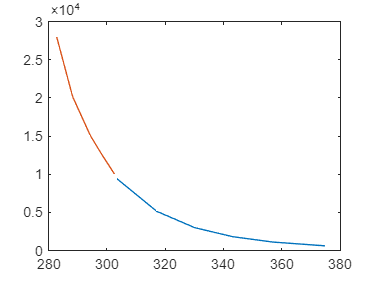


plot(A, B , AA ,BB)


% Determinando parámetros 
syms aplus bplus cplus
T1p = AA(1) == (aplus + bplus*log10(BB(1)) + cplus*log10(BB(1))^3 )^-1

$$T1p = \frac{5657}{20}=\frac{1}{\mathrm{aplus}+\frac{5005305358324921\,\mathrm{bplus}}{1125899906842624}+\frac{24150838760303\,\mathrm{cplus}}{274877906944}}$$

T3p = A(3) ==  (aplus + bplus*log10(B(3))  + cplus*log10(B(3))^3 )^-1

$$T3p = \frac{6603}{20}=\frac{1}{\mathrm{aplus}+\frac{122340328024043\,\mathrm{bplus}}{35184372088832}+\frac{5916560413321681\,\mathrm{cplus}}{140737488355328}}$$

T6p = A(6) ==  (aplus + bplus*log10(B(6))  + cplus*log10(B(6))^3 )^-1

$$T6p = \frac{7497}{20}=\frac{1}{\mathrm{aplus}+\frac{6286328483330351\,\mathrm{bplus}}{2251799813685248}+\frac{1531022863008511\,\mathrm{cplus}}{70368744177664}}$$

% 1p 3 6
sol5 = solve([T1p,T3p,T6p],[aplus,bplus,cplus]);
aplus = vpa(sol5.aplus)

$$aplus = 0.0011830444633974709392585474734169$$

bplus = vpa(sol5.bplus)

$$bplus = 0.00053356473910454358660429596628978$$

cplus = vpa(sol5.cplus)

$$cplus = -0.0000002233011901599802763173956183599$$

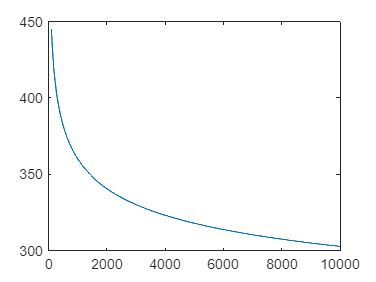


%Grafico ecuacion
x = linspace(100,10000,1000);
SH_1p36= (aplus  + bplus.*log10(x) + cplus.*log10(x).^3 ).^-1;
plot(x,SH_1p36)


%Valor de muestra
r1 = 10000;
SH_1p36 = (aplus + bplus.*log10(r1)+ cplus.*log10(r1).^3 ).^-1

$$SH\_1p36 = 302.7539580573078786406067307603$$


SH_1p36 - 273.15

$$ans = 29.603958057307878640606730760296$$

## With all values

% --- 1. Data Definition ---
xData = [282.85, 287.95, 288.45, 294.35, 298.25, 302.65, 303.65, 317.15, 330.15, 343.15, 356.85, 374.85];
yData = [27900, 20600, 20000, 15050, 12600, 10000, 9350, 5130, 3000, 1820, 1120, 619];

% --- 2. Data Transformation ---
% The model fits the inverse of xData using a function of log10(yData).
yData_log = log10(yData);   % Independent variable (input to the fit)
xData_inv = 1 ./ xData;     % Dependent target (output of the fit)

% --- 3. Model Function Definition ---
% The function models the relationship: 1/x = z(1) + z(2)*log10(y) + z(3)*log10(y)^3
fun_poly = @(z, yData_log) z(1) + z(2) * yData_log + z(3) * yData_log.^3;

% --- 4. Solver Setup and Fit ---
% Initial guess for the parameters [z1, z2, z3]
z0 = [1e-3, 1e-3, 1e-6]; 
options = optimoptions('lsqcurvefit', ...
    'Algorithm', 'levenberg-marquardt', ...  
    'MaxIterations', 1000, ...               
    'Display', 'final'); 

% Execute the fit: fitting z to model xData_inv based on yData_log
[z_fit, resnorm, residual, exitflag, output] = lsqcurvefit(fun_poly, z0, yData_log, xData_inv, [], [], options);


Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


disp(['Exit Flag: ', num2str(exitflag)]);

Exit Flag: 1


vpa([z_fit(1) z_fit(2) z_fit(3)]')

$$ans = \left(\begin{array}{c} 0.0011786017203519140103540330244414\\ 0.0005344656896189127828766807226657\\ -0.00000017949898312034535854688724765965 \end{array}\right)$$

% --- 5. Goodness of Fit (R-squared) ---
y_target = xData_inv;
y_mean = mean(y_target);

SS_res = resnorm; % Sum of Squares of Residuals (from lsqcurvefit output)
SS_tot = sum((y_target - y_mean).^2); % Total Sum of Squares

R_squared = 1 - (SS_res / SS_tot);
R = sqrt(R_squared);

disp(['R-squared (R^2): ', num2str(R_squared)]);

R-squared (R^2): 0.99992


disp(['Correlation Coefficient (R): ', num2str(R)]);

Correlation Coefficient (R): 0.99996


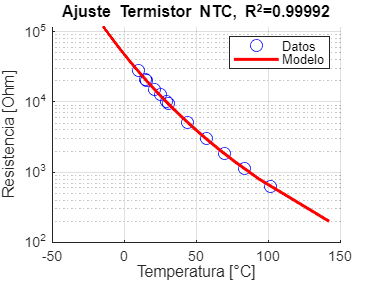


% --- 6. Plotting the Result ---
% The original model function, used to generate the smooth fit line
original_fun = @(z, yData) (z(1) + z(2) * log10(yData) + z(3) * log10(yData).^3).^-1;

% Create a smooth range for the y-axis (resistance)
% y_plot = linspace(min(yData), max(yData), 100);
y_plot = linspace(2e2, 1.2e5, 200);


% Generate the fitted x-values (temperature)
x_fit_plot = original_fun(z_fit, y_plot);

% Convert temperature (xData) to Celsius for plotting (assuming xData is Kelvin)
xData_C = xData - 273.15;
x_fit_plot_C = x_fit_plot - 273.15;

createfigure_termistor(xData_C, yData, x_fit_plot_C, y_plot)


% figure;
% hold on; 
% % Plot the original data points
% plot(xData_C, yData, 'bo', 'MarkerSize', 8, 'DisplayName', 'Datos'); 
% 
% % Plot the fitted curve
% plot(x_fit_plot_C, y_plot, 'r-', 'LineWidth', 2, 'DisplayName', 'Modelo'); 
% 
% xlabel('Temperatura [°C]');
% ylabel('Resistencia [Ohm]');
% title(['Ajuste Steinhart-Hart, R^2=', num2str(R_squared, 5)]);
% legend('Location', 'northeast');
% grid on;
% hold off;

original_fun(z_fit, 10000)-273.15

ans =     29.4240e+000


# Loop compensation (Analog devices)

## Compensation loop stock

Vout = 5;
Cout = 2*47e-6

Cout =     94.0000e-006


Iout_max = 3.5;
Vref = 0.8;
Fp_mod = Iout_max/(2*pi()*Vout*Cout)

Fp_mod =      1.1852e+003


%C94 -> 1k69
%C66 -> 2k4

Gain_margin_eA = 92e-6;

% Gain_margin = 20000
% Gain_pwr_stage = -5.1
Gain_pwr_stage = -5.1

Gain_pwr_stage =     -5.1000e+000



erres = linspace(-20,20,100)

erres =    -20.0000e+000   -19.5960e+000   -19.1919e+000   -18.7879e+000   -18.3838e+000   -17.9798e+000   -17.5758e+000   -17.1717e+000   -16.7677e+000   -16.3636e+000   -15.9596e+000   -15.5556e+000   -15.1515e+000   -14.7475e+000   -14.3434e+000   -13.9394e+000   -13.5354e+000   -13.1313e+000   -12.7273e+000   -12.3232e+000   -11.9192e+000   -11.5152e+000   -11.1111e+000   -10.7071e+000   -10.3030e+000    -9.8990e+000    -9.4949e+000    -9.0909e+000    -8.6869e+000    -8.2828e+000    -7.8788e+000    -7.4747e+000    -7.0707e+000    -6.6667e+000    -6.2626e+000    -5.8586e+000    -5.4545e+000    -5.0505e+000    -4.6465e+000    -4.2424e+000    -3.8384e+000    -3.4343e+000    -3.0303e+000    -2.6263e+000    -2.2222e+000    -1.8182e+000    -1.4141e+000    -1.0101e+000  -606.0606e-003  -202.0202e-003



% syms xx
R3 = (10 ^ (Gain_pwr_stage/20))/(Gain_margin_eA) * (Vout/Vref)

R3 =     37.7652e+003


% R3 = @(xx) (10.^(xx./20))./(Gain_margin_eA)*(Vout./Vref)
%GM = 27272
% plot(erres, R3(erres))

Fco = 20000;
C6 = 1 / (2*pi()*R3*(Fco/10))

C6 =      2.1072e-009



C6 = 1e-9;
C7 = 1/(2*pi()*R3*10*Fco)

C7 =     21.0716e-012


## Compensation loop

Vout = 5;
Cout = 66e-6

Cout =     66.0000e-006


Iout_max = 3.5;
Vref = 0.8;
Fp_mod = Iout_max/(2*pi()*Vout*Cout)

Fp_mod =      1.6880e+003


%C94 -> 1k69
%C66 -> 2k4

Gain_margin_eA = 92e-6;

Gain_pwr_stage = -7.

Gain_pwr_stage =     -7.0000e+000



erres = linspace(-20,20,100)

erres =    -20.0000e+000   -19.5960e+000   -19.1919e+000   -18.7879e+000   -18.3838e+000   -17.9798e+000   -17.5758e+000   -17.1717e+000   -16.7677e+000   -16.3636e+000   -15.9596e+000   -15.5556e+000   -15.1515e+000   -14.7475e+000   -14.3434e+000   -13.9394e+000   -13.5354e+000   -13.1313e+000   -12.7273e+000   -12.3232e+000   -11.9192e+000   -11.5152e+000   -11.1111e+000   -10.7071e+000   -10.3030e+000    -9.8990e+000    -9.4949e+000    -9.0909e+000    -8.6869e+000    -8.2828e+000    -7.8788e+000    -7.4747e+000    -7.0707e+000    -6.6667e+000    -6.2626e+000    -5.8586e+000    -5.4545e+000    -5.0505e+000    -4.6465e+000    -4.2424e+000    -3.8384e+000    -3.4343e+000    -3.0303e+000    -2.6263e+000    -2.2222e+000    -1.8182e+000    -1.4141e+000    -1.0101e+000  -606.0606e-003  -202.0202e-003



% syms xx
R3 = (10 ^ (Gain_pwr_stage/20))/(Gain_margin_eA) * (Vout/Vref)

R3 =     30.3454e+003


% R3 = @(xx) (10.^(xx./20))./(Gain_margin_eA)*(Vout./Vref)
%GM = 27272
% plot(erres, R3(erres))

Fco = 20000;
C6 = 1 / (2*pi()*R3*(Fco/10))

C6 =      2.6224e-009



C6 = 1e-9;
C7 = 1/(2*pi()*R3*10*Fco)

C7 =     26.2239e-012


## Analog stock

Ceq = 94e-6;
ESR = 10e-6;
Rload = 5/5;
Fp = (2*pi()*Ceq*Rload)^-1

Fp =      1.6931e+003


Fz = (2*pi()*Ceq*ESR)^-1

Fz =    169.3138e+006


fe

R1 = 37400;
R3 = 10200;
gainbzp = 20*log10(R1/R3)

gainbzp =     11.2854e+000




C1 = 2.2e-9;
C2 = 22e-12;
Xeq = ((2*pi()*C1)^-1 + (2*pi()*C2)^-1)^-1

Xeq =    136.8615e-012


gainrz = 20*log10(Xeq/R3)

gainrz =   -277.4464e+000



C1 = Ceq*Rload/R1

C1 =      2.5134e-009


C2 = Ceq*ESR/R1

C2 =     25.1337e-015



Xeq = ((2*pi()*C1)^-1 + (2*pi()*C2)^-1)^-1

Xeq =    157.9181e-015



gainrz = 20*log10(Xeq/R3)

gainrz =   -336.2034e+000


## Analog 

Ceq = 66e-6;
ESR = 3e-6;
Rload = 5/3.5;
Fp = (2*pi()*Ceq*Rload)^-1

Fp =      1.6880e+003


Fz = (2*pi()*Ceq*ESR)^-1

Fz =    803.8128e+006


fe

R1 = 84000;
R3 = 16000;
gainbzp = 20*log10(R1/R3)

gainbzp =     14.4032e+000




C1 = 13.82e-9;
C2 = 1.382e-12;
Xeq = ((2*pi()*C1)^-1 + (2*pi()*C2)^-1)^-1

Xeq =      8.6825e-012


gainrz = 20*log10(Xeq/R3)

gainrz =   -305.3095e+000




C1 = Ceq*Rload/R1

C1 =      1.1224e-009


C2 = Ceq*ESR/R1

C2 =      2.3571e-015



Xeq = ((2*pi()*C1)^-1 + (2*pi()*C2)^-1)^-1

Xeq =     14.8103e-015



gainrz = 20*log10(Xeq/R3)

gainrz =   -360.6711e+000


## Analog real

Ceq = 66e-6;
ESR = 3e-6;
Rload = 5/3.5;
Fp = (2*pi()*Ceq*Rload)^-1

Fp =      1.6880e+003


Fz = (2*pi()*Ceq*ESR)^-1

Fz =    803.8128e+006


fe

R1 = 37400;
R3 = 10200;
gainbzp = 20*log10(R1/R3)

gainbzp =     11.2854e+000




C1 = 2.2e-9;
C2 = 22e-12;
Xeq = ((2*pi()*C1)^-1 + (2*pi()*C2)^-1)^-1

Xeq =    136.8615e-012


gainrz = 20*log10(Xeq/R3)

gainrz =   -277.4464e+000



C1 = Ceq*Rload/R1

C1 =      2.5210e-009


C2 = Ceq*ESR/R1

C2 =      5.2941e-015



Xeq = ((2*pi()*C1)^-1 + (2*pi()*C2)^-1)^-1

Xeq =     33.2639e-015



gainrz = 20*log10(Xeq/R3)

gainrz =   -349.7326e+000
